# Darik O'Neil, Jackie Niu, Noah Simon MBL Neuro 2021 Team Hoppa

% Munchies for Munchkins Code (Project 1)

%Script designed to take '*mat' files containing cells in the form row =
%trial and column = condition where [row,col] is the time of initiation and
%headers are conditions

%Uses for MBL Project 1 to assess effects of WIN-55,212-2 and AM-251 on
%presynaptic plasticity at single-synapse resolution using a variety of
%optical sensors.

%All ROIs have been manually annotated using FIJI

## Compile .csv's into .xlsx

cellID = '15'; %Insert Cell ID
Indicator = 'glusnfr'; %Insert Indicator (glusnfr or gcamp)
[~] = csv2excel(cellID,Indicator);

## Set Parameters

framerate = 52.63; %framerate in frames / second

## Import Timing, Indices, & Conditions

timerecording = uigetfile('*.mat'); %Select T.I.C. file
[conditions, indices, times] = readstim(timerecording); %Import T.I.C.

## Import ROI data

[ExperimentalStack]=importROIs(conditions, indices, times, framerate); %import the raw data & generate experimental data structure
ExperimentalStack.timefilename = timerecording; %store time filename before memory tidying
[ExperimentalStack] = makeTimeVector(ExperimentalStack); %generate time vectors for plotting
clear conditions indices times timerecording framerate; %clean up memory

## Generate Global ROI Intensities

[ExperimentalStack] = generateGlobal(ExperimentalStack);

## Plot 

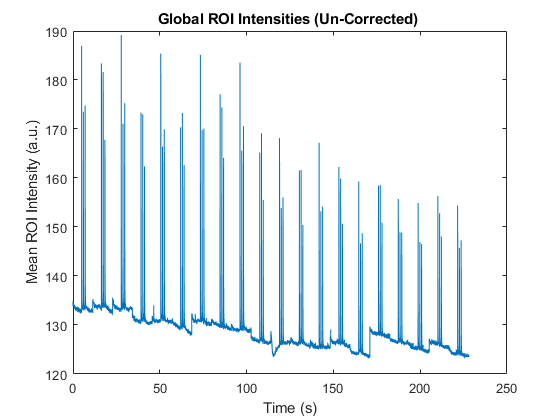

F = figure;
plot(ExperimentalStack.GlobalTimeVector_s,ExperimentalStack.Global_SynROIs);
title('Global ROI Intensities (Un-Corrected) ');
ylabel('Mean ROI Intensity (a.u.)');
xlabel('Time (s)');

%saveas(F,filename,formattype)

## Process ROI Intensities Using Anisotropic Diffusion

ExperimentalStack.gT=15;
[ExperimentalStack] = anisotropicDiffusionBatch(ExperimentalStack);

## Plot

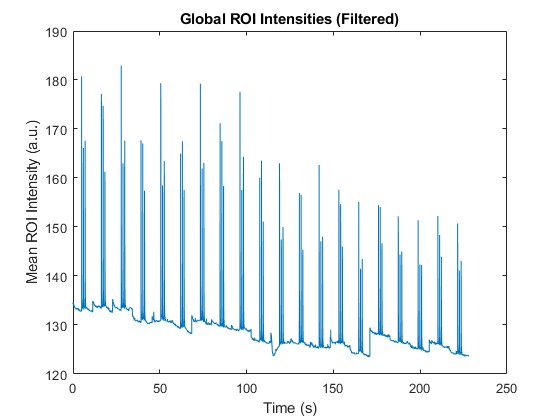

F = figure;
plot(ExperimentalStack.GlobalTimeVector_s,ExperimentalStack.Global_SynFilt);
title('Global ROI Intensities (Filtered)');
ylabel('Mean ROI Intensity (a.u.)');
xlabel('Time (s)');

%saveas(F,filename,formattype)

## Normalize ROI Intensities using F-Fo/Fo

[ExperimentalStack] = findSyn_dF_Fo_Batch(ExperimentalStack);

## Plot

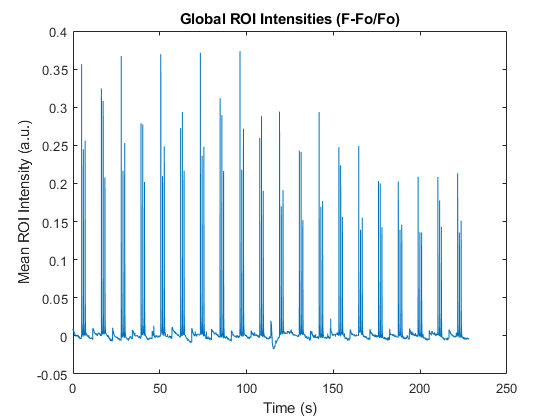

F = figure;
plot(ExperimentalStack.GlobalTimeVector_s,ExperimentalStack.Global_Syn_dF_Fo);
title('Global ROI Intensities (F-Fo/Fo)');
ylabel('Mean ROI Intensity (a.u.)');
xlabel('Time (s)');

%saveas(F,filename,formattype)

## Calculate First Time Derivative (Filtered)

[ExperimentalStack] = find_dFdT_Batch(ExperimentalStack);

## Plot

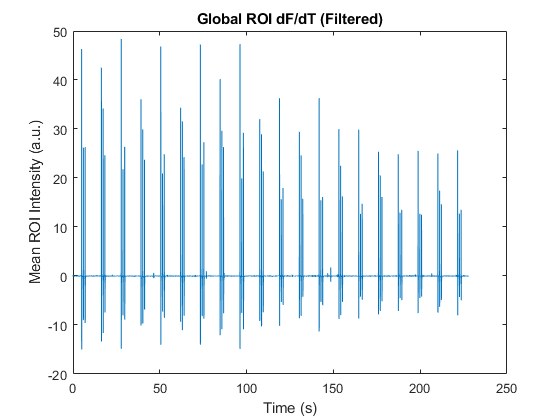

F = figure;
plot(ExperimentalStack.GlobalTimeVector_s,ExperimentalStack.Global_Syn_dFdT);
title('Global ROI dF/dT (Filtered)');
ylabel('Mean ROI Intensity (a.u.)');
xlabel('Time (s)');

%saveas(F,filename,formattype)

## Calculate First Time Derivative (F-Fo/Fo)

[ExperimentalStack] = find_dFdTFo_Batch(ExperimentalStack);

## Plot

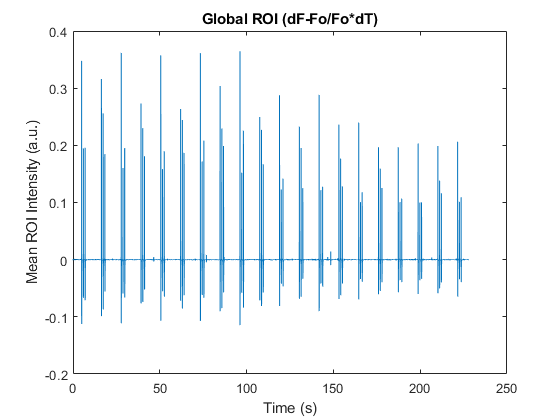

F = figure;
plot(ExperimentalStack.GlobalTimeVector_s,ExperimentalStack.Global_Syn_dFdTFo);
title('Global ROI (dF-Fo/Fo*dT)');
ylabel('Mean ROI Intensity (a.u.)');
xlabel('Time (s)');

%saveas(F,filename,formattype)